# Experimental Testing of PEMFC unit 

[⇦ Return to the main menu](matlab:open('..\MainMenu.m'))

In this script, you will set up and run the PEMFC system experiment to observe performance and collect data. The system performance is based on measuring voltage and current variables. The MATLAB logger acts as the central communication hub with the laboratory instruments.

Complete Data Flow:

Sensors

   ↓

MATLAB Logger

   ↓

CSV File (Local Storage)

## **Before you get started**

Consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if they run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## 1. Introduction and background on fuel cells

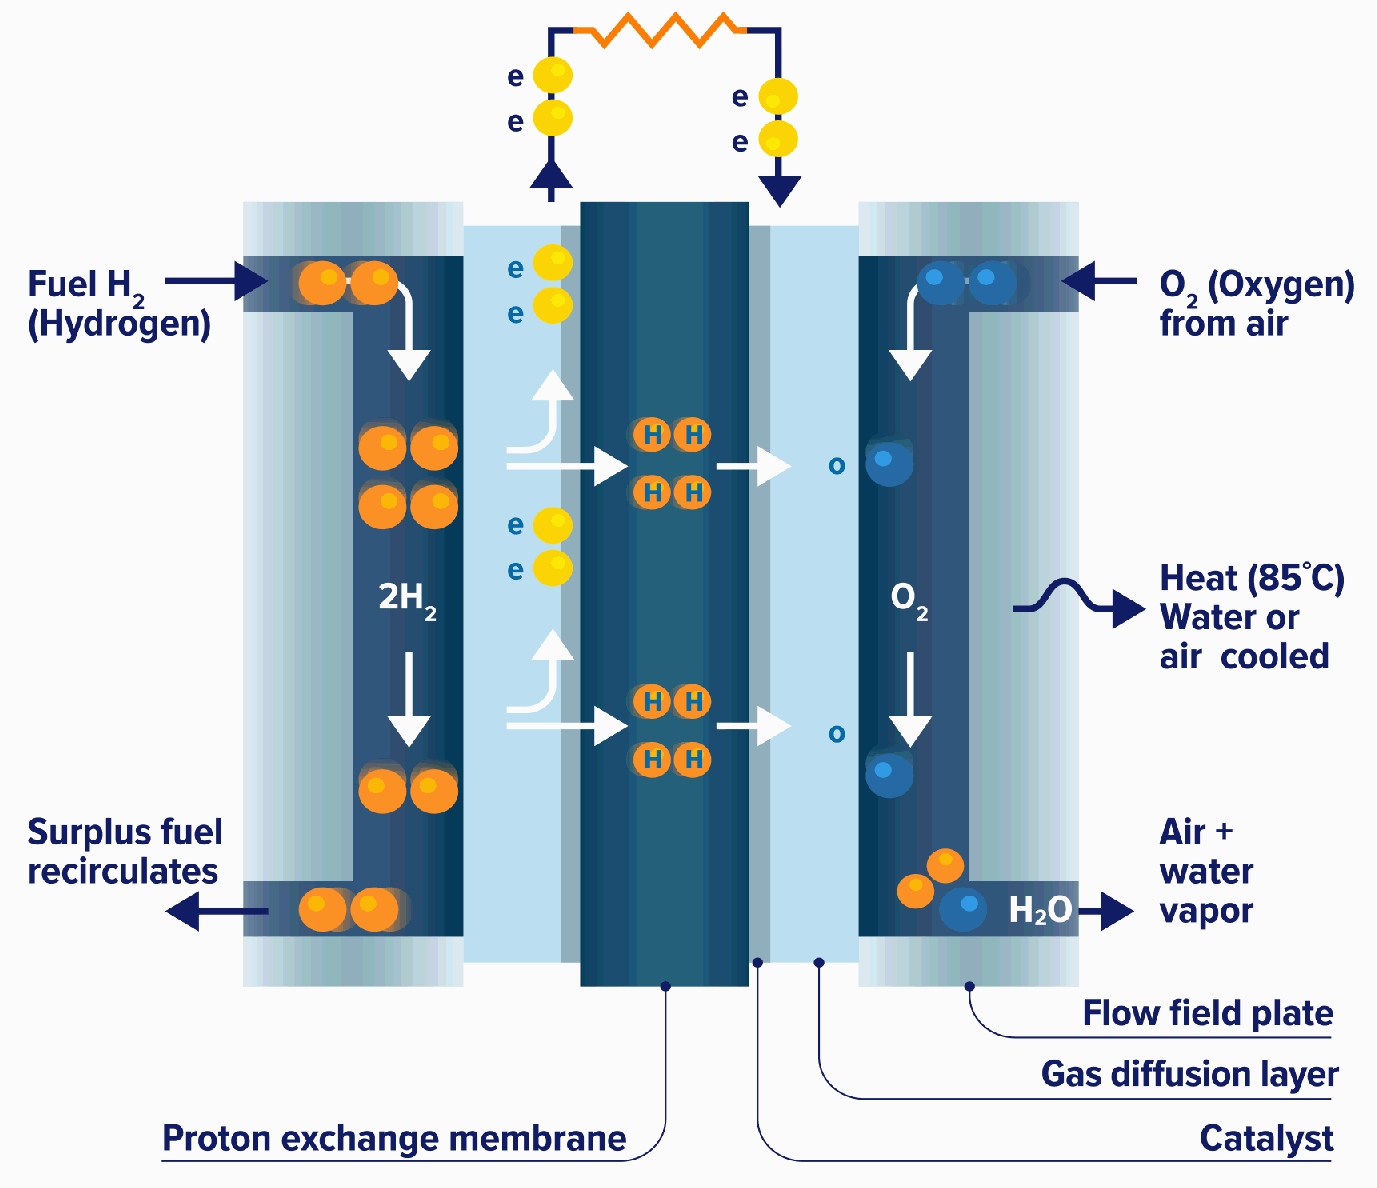

Figure 1. Fuel cell schematic

A PEM fuel cell converts the **chemical energy of hydrogen and oxygen directly into electrical energy**, with water and heat as byproducts. The core components of a PEMFC include:

- Anode: Hydrogen is supplied and split into protons (H⁺) and electrons (e⁻)

- Proton Exchange Membrane (PEM): Allows only protons to pass through

- Cathode: Oxygen combines with protons and electrons to form water

- External circuit: Electrons flow through a load, producing usable electrical power

Key advantages of PEM fuel cells include:

- Low operating temperature (typically <60 °C)

- High power density

- Fast startup and good transient response

- Compact and modular design

However, PEMFC performance depends on complex, coupled **electrochemical, thermal, and fluid transport phenomena**, making them an ideal platform for system and process modeling. Here the key physical variables are measured by setting up and testing a small scale PEMFC unit to inform us about the performance of the PEMFC which is typically dictated by the electric power generated and temperature. To obtain power, fuel cell voltage has to be measured based on the load and fuel cell current, which is the input variable that can be manipulated. The electric power is the product of voltage and current. The temperature measured is a function of the air flow, hydrogen flow and current due to heat transfer and fuel cell losses.  

## 2. Hardware Setup and Operating Procedure of PEMFC System

**Operating Conditions**

- Hydrogen purity ≥ 99.995% 

- Pressure: 0.45–0.55 bar

- Flow Tube: length < 30 cm, diameter > 2 mm 

- Operate in a ventilated environment and avoid vibration 

- Disconnect hydrogen immediately after shutdown 

This is the fuel cell system testing setup with fuel cell, electrolyzer/hydrogen generator, power supply and load generator with all sensors connected to a DAQ system and a computer.

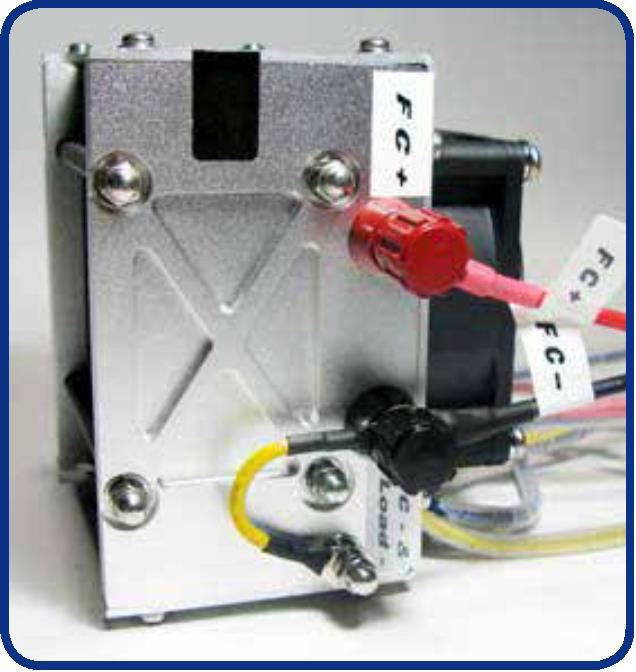

H-100 PEM fuel cell stack (20 cells, 100 W rated power) is selected for this testing. Detailed specifications can be found in manual of [Horizon H-100 PEM fuel cell](https://www.horizoneducational.com/h-100-pem-fuel-cell-100w/p1248?currency=usd) .

## 3. How to Connect the PEMFC System to a Desktop Computer

**Step 1: System Setup and Connection**

- Follow the instructions in the manual of [Horizon H-100 PEM fuel cell](https://www.horizoneducational.com/h-100-pem-fuel-cell-100w/p1248?currency=usd) on setting up the controller to power supply of 13V and fuel cell stack, fuel cell stack to load, hydrogen supply and purge valves connected to controller and the fuel cell, and connect sensors from fuel cell stack and hydrogen supply.   

- Verify that all electrical connections follow the manual.

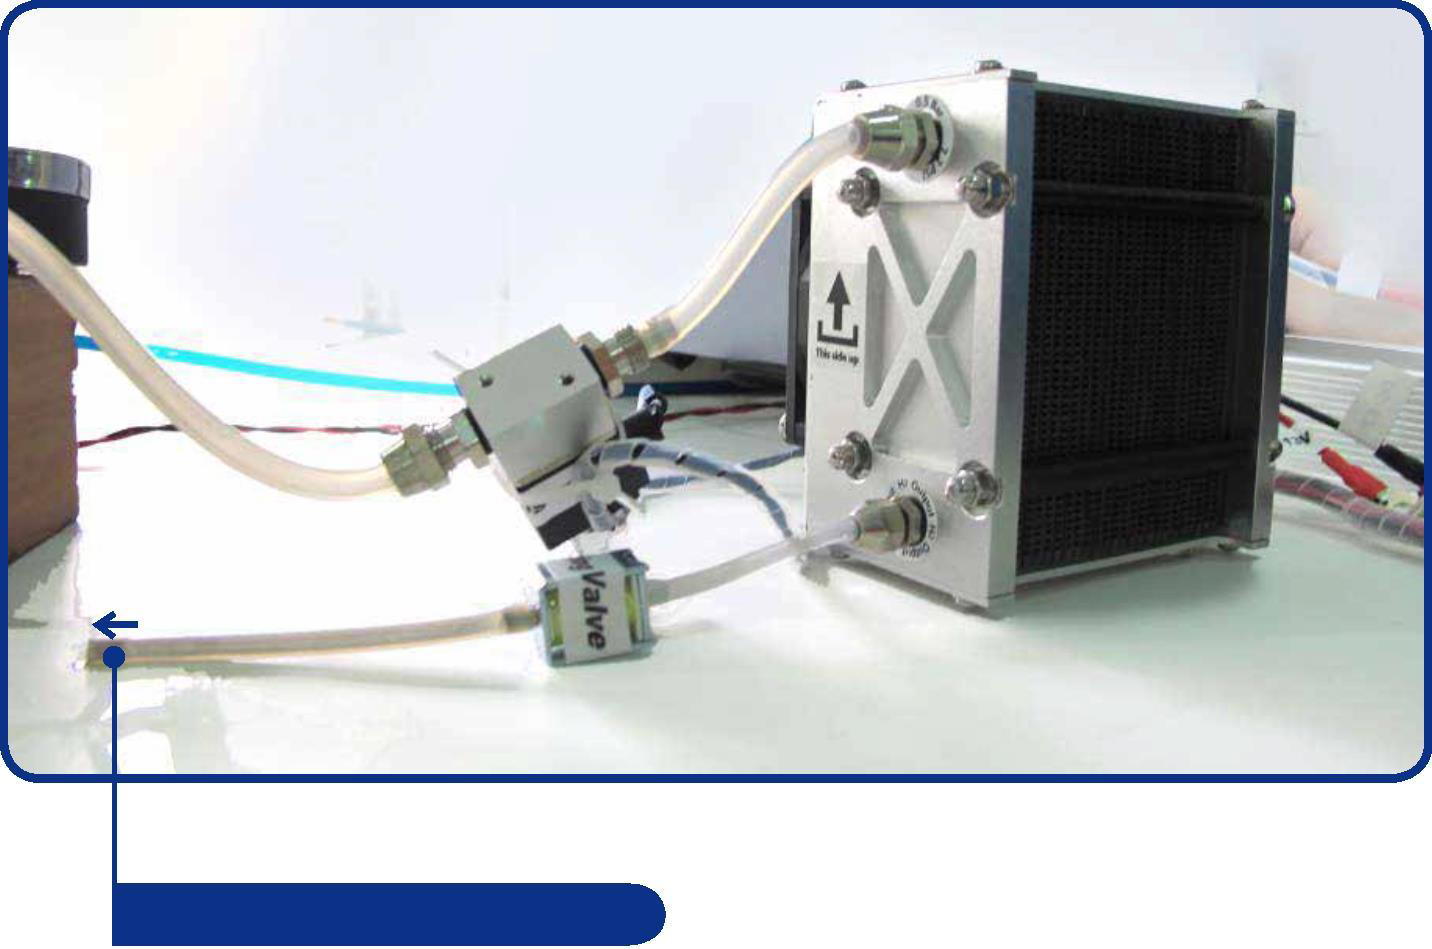

Hydrogen supply and purge valves connected to fuel cell stack

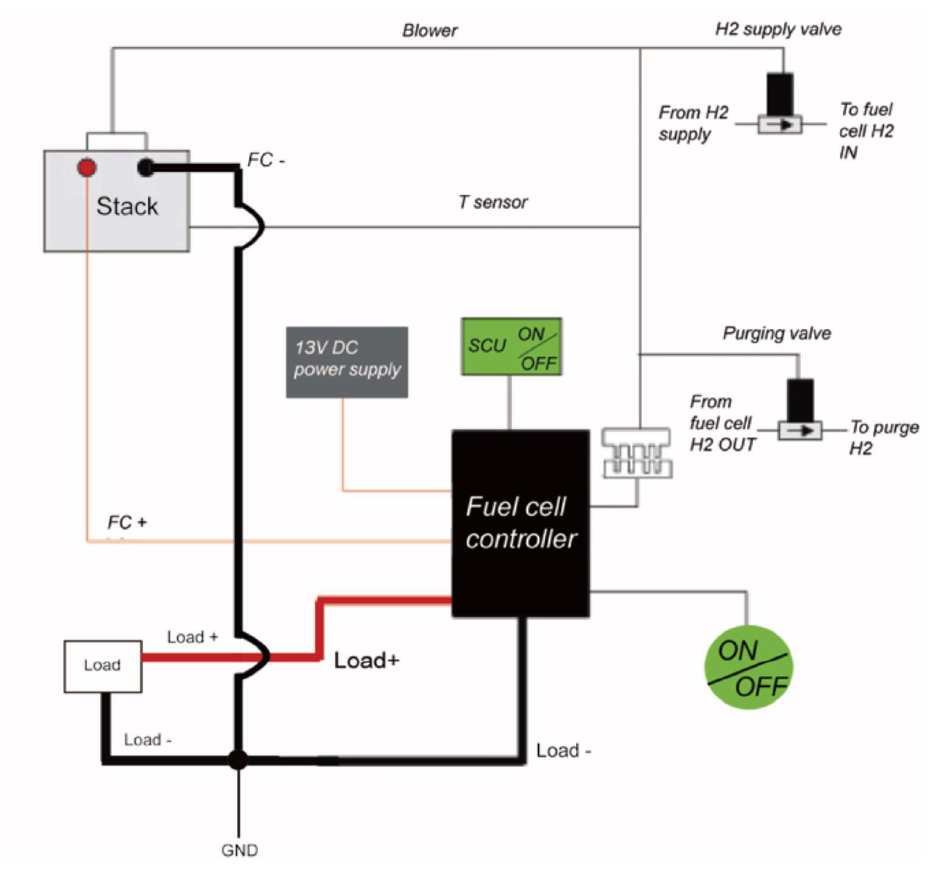

Overall schematic of the fuel cell stack connected to load and controller along with supply and purge valves.

**Step 2: Fuel supply Connection**

- Set up the hydrogen generator, which is basically an alkaline electrolyzer, following the instructions in the manual, which in this case, is for [SHC-1000 Alkaline electrolyzer](https://www.fuelcellstore.com/alkaline-hydrogen-generator-shc-1000). The electrolyzers requires a solution of 640 g per liter of H₂O where this belongs in one of the tanks while the right-hand tank contains deionized (desalted) water. The left-hand tank contains the electrolyte solution.

- Connect the electrolyzer hose or tube from the hydrogen outlet port to the inlet port of the flow sensor. Thereafter, the outlet port of the hydrogen flow sensor then connects to the fuel cell (hydrogen) supply valve and input port to measure the hydrogen flow, pressure and temperature to the stack.

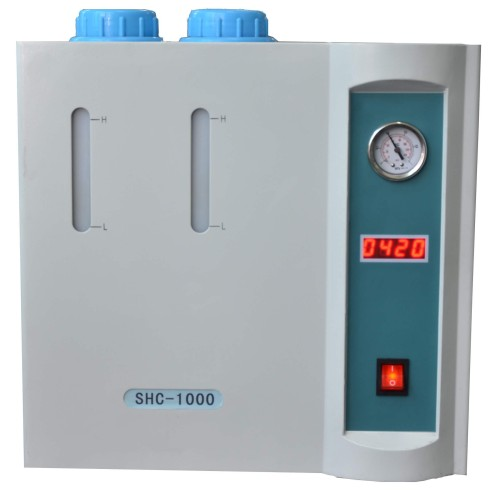

Hydrogen generator system that can supply up to 1 SLPM of fuel 

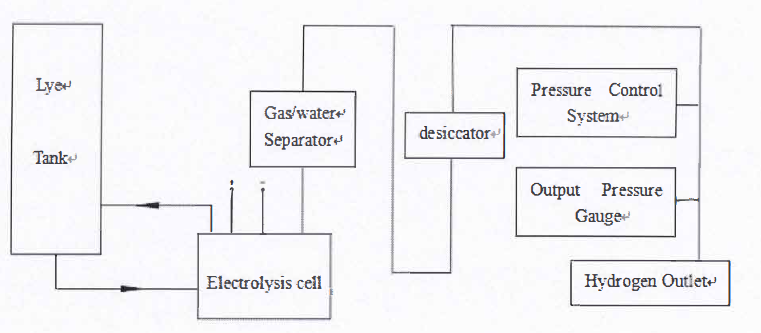

Overall schematic of the hydrogen generator that produces hydrogen using alkaline electrolysis process.

**Step 3: Sensor and DAQ Connection**

- Place a thermocouple at the back of the PEMFC to measure the approximate overall PEMFC temperature

- Three sets of sensors of thermocouples, voltage & current, and flow sensors were added along with DAQ system to connect to computer

**Step 4: Load Connection**

- Connect electrical load (such as [load generator from National Instruments](https://docs-be.ni.com/bundle/rmx-400x-command-ref/raw/resource/enus/378076a.pdf)) to fuel cell output. 

- Using the fuel cell controller and load generator, the system can be operated at various operating conditions based on the polarization (voltage-current) curve provided in the manual, for example the fuel cell used in this example operates at 0.7 A and 13 V 

- The system is now operational. 

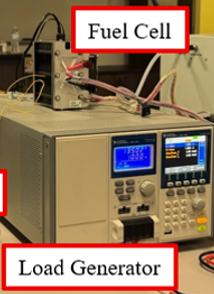

Load generator can be connected using the load wires to the fuel cell stack.

Here's a video of the setup:

## **4. Measurement and Calculation **

Goal:

- Measure voltage (V) and current (I) 

- Electric Power: 


$$P_{\mathrm{elec}} =V\bullet I$$


 **Exercise.**  Estimate the electric power for the fuel cell for the example operating condition.

%V = voltage [V]
V=NaN
%I = current [A]
I=NaN
% Electrical power is calculated from: #need help here with check answer
P_elec = V*I
% where P_elec = electric power [W]
CheckAnswer(V, I, P_elec)
 


###  **Activity 1 — Use MATLAB Copilot to Improve a Power-Calculation Prompt:**

**Learning objective**

Use MATLAB Copilot to compare a general prompt with a structured engineering prompt.

**Instructions**

The previous exercise calculated the electrical power of the fuel cell using:

P_elec = V*I

You will now use MATLAB Copilot to determine how the quality of a prompt affects the generated explanation and MATLAB code.

**Part A: Initial prompt: Submit a general prompt**

Go to <Home>, Navigate to <Copilot Chat> Open MATLAB Copilot Chat and submit the initial prompt shown below. Review the answer.

"Calculate the electrical power of a fuel cell."

Review the response and note what information is missing.

**Part B: Improved prompt**

Submit this second prompt:

" PEM fuel cell operates at 13 V and 0.7 A. Use P=V*I to calculate its electrical power. Generate MATLAB code and report the result in Watts."

Compare the two Copilot responses.

**Reflection**

- How many options or methods did the first prompt produce? Why would there be more than one?

- What information in the improved prompt made the response more specific? 

- Did the Copilot result agree with the previous MATLAB calculation? Yes

## **5. How to Collect Data from a PEMFC experiment**

The MATLAB logger acts as the  communication hub between the laboratory instruments and the computer storage. Make sure to include any relevant add-on packages or files.

Here's the Data Flow:

Sensors

   ↓

MATLAB Logger

   ↓

CSV File (Local Storage)

**Laboratory Instruments**

Overall diagram of the fuel system, hydrogen generator, controller, load generator, DAQ and computer

### Step 1: Connect MATLAB to the Instruments

Split into three subsections:

- **Thermocouple Connection**

**Purpose:** `Connect MATLAB to the thermocouple and measure PEMFC temperature.`

- **RMX-4000 Connection**

**Purpose: **`Connect MATLAB to the electronic load and acquire voltage and current measurements.`

- **Omega Flow Meter Connection**

**Purpose: **`Acquire pressure, flow-rate, and gas information. A full script to collect data from PEMFC live was created using the information earlier. The code has to be edited based on the ports and devices connected to the DAQ system.`

### Step 2: Acquire PEMFC Measurements

Place all reading operations together.

- **Temperature**

- **Voltage and Current**

- **Flow Meter Data**

  **Try. **Inform the board you are using for the sensors.

"Arduino Mega"

### Step 3: Store Experimental Data Locally

Why Save a CSV File?

Local storage provides:

- Permanent experiment records

- Backup in case of internet failure

- Access to high-frequency measurements

- Post-processing and analysis capabilities

CSV Header Example

Note: The digital pins on the Arduino will allow us to read voltage, current, temperature and flow values from the sensors.

Here's an example set of PEMFC data collected using this approach to observe and later to analyze and model.

load PEMFCdata.mat
% open variable to look at the PEMFC data
data
Vfc=data.Voltage_V_;
Ifc=data.Current_A_;
t_fc=data.Time_s_;

 

PlotPEMFC(t_fc,Ifc,Vfc)
 

**Reflection**

- What do you notice from the graphs of current and voltage? 

- Do you see the voltage and current values? 

- Do you observe the voltage behavior change as current changes?

### **Activity 2 — ** Plotting experimental data

**Learning objective**

Use MATLAB plot to identify PEMFC measurements to understand the behavior based on the collected data. 

Prompt 1:

" What is the nominal operating voltage of 100W Horizon fuel cell?"

The response should include a value around 12V.

Prompt 2:

" What is the approximate corresponding current?"

Prompt 3:

"What are the sudden spikes or drops in the 100 W Horizon fuel cell?"

There should a short discussion including mention of purging in fuel cells to optimize performance.

### **Activity 3 — ** Debugging

**Learning objective**

Use MATLAB Copilot to identify and correct mismatched PEMFC measurement-array lengths without inventing missing data.

**Instructions:**

Run the code, ask Copilot to diagnose the error, apply the safest correction, and confirm that the table is created successfully.

time_s = [0 1 2 3 4];
voltage_V = [13.1 13.0 12.9 12.8];
current_A = [0.5 0.6 0.7 0.8 0.9];

dataTable = table(time_s', voltage_V', current_A', ...
    'VariableNames', {'Time_s','Voltage_V','Current_A'});
 

Use the following prompts to help you debug the code, understand the cause of the error, and apply a safe correction without inventing missing experimental data.

Prompt 1:

Copy and paste the code and then ask " Explain the MATLAB error produced by this code and identify which measurement array causes the problem."

Prompt 2:

 "Suggest the minimum correction needed to create the table while keeping the PEMFC measurements synchronized. Do not invent a missing voltage value."

Prompt 3:

"Explain why all table variables must contain the same number of rows and how this affects experimental data integrity."

Share the Fixed code down below (you may run it using proper code format):

The corrected table should contain exactly **4 synchronized measurements**:

- Time: **0, 1, 2, 3 s**

- Voltage: **13.1, 13.0, 12.9, 12.8 V**

- Current: **0.5, 0.6, 0.7, 0.8 A**

## Helper Functions

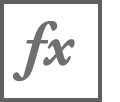`CheckAnswer`

function CheckAnswer(V,I,P_elec)

    if isnan(V) || isnan(I)
        disp("Enter values for V and I")
        return
    elseif P_elec == 9.1
        disp("This is correct.")
    else 
        warning("Please try again")
    end

end

[⇦ Return to the main menu](matlab:open('..\MainMenu.m'))

Copyright